# WLAN Beacon Receiver Using Software-Defined Radio

This example shows how to retrieve information about WiFi® networks on either 2.4 GHz or 5 GHz band using a software-defined radio (SDR). The example scans over  2.4 GHz or 5 GHz band beacon channels and captures waveforms for analysis within MATLAB®. The example then decodes the direct-sequence spread spectrum/orthogonal frequency-division multiplexing (DSSS/OFDM) packets to determine which packets are access point (AP) beacons. The AP beacon information includes the service set identifier (SSID), media access control (MAC) address (also known as the basic SSID, or BSSID), AP channel bandwidth, and 802.11 standard used by the AP.

## Introduction

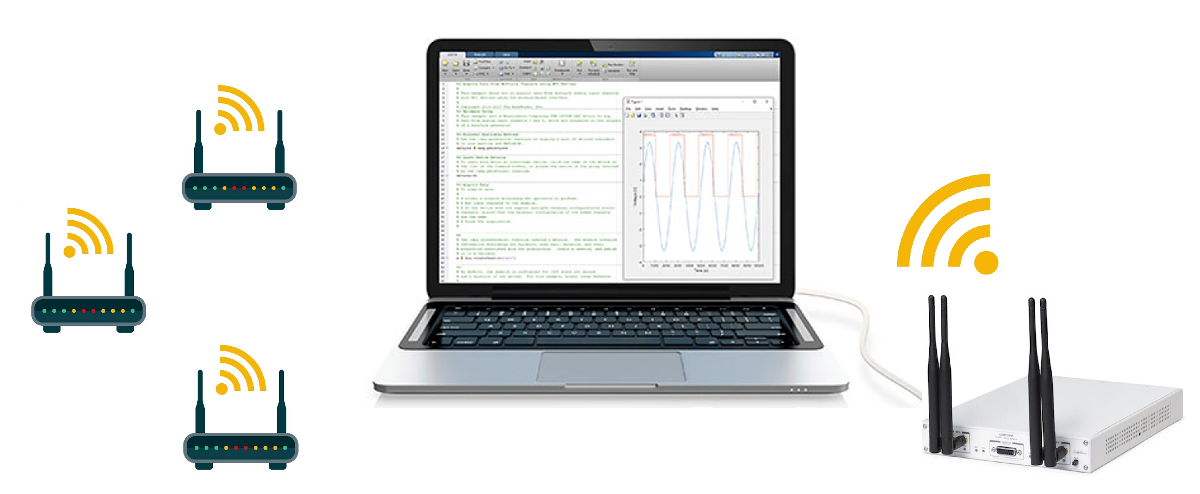

This example scans through a set of WiFi® channels in 2.4 GHz or 5 GHz band to detect AP beacons. In the 2.4 GHz band, beacons are most commonly transmitted with DSSS modulation. In the 5 GHz band, beacons are always transmitted with OFDM modulation. The example supports the following three configuration modes:

- **OFDM, band 5:** Searches for OFDM beacons in the 5 GHz band with 20 MHz sample rate.

- **OFDM, band 2.4:** Searches for OFDM beacons in the 2.4 GHz band with 20 MHz sample rate.

- **DSSS, band 2.4:** Searches for DSSS beacons in the 2.4 GHz band with 11 MHz sample rate.

The scanning procedure comprises of these steps.

- Set the frequency band and channels for the SDR to capture.

- Capture a waveform for a set duration for each specified channel.

- Process the waveform in MATLAB by searching for beacon frames in the captured waveform and extracting relevant information from each successfully decoded beacon frame.

- Display key information about the detected APs.

## **Required Hardware and Software**

By default, this example runs using recorded data from a file. Optionally, you can receive signals over-the air by using these hardware:

- ADALM-PLUTO radio and Communications Toolbox Support Package for Analog Devices® ADALM-PLUTO Radio. For more information, see [ADALM-Pluto Radio](docid:comm_doccenter#mw_0e7ad01a-dc12-4f4d-bd42-54dc112c2e1d).

- USRP™ E310/E312 radio and Communications Toolbox Support Package for USRP™ Embedded Series Radio. For more information, see [USRP Embedded Series Radio](docid:comm_doccenter#mw_eaac0336-4b33-4e96-9c62-3fe07bf7e726).

- USRP N2xx or B2xx series radio and Communications Toolbox Support Package for USRP Radio. For more information, see [USRP Radio](docid:comm_doccenter#mw_de5fc03d-bc6e-471f-8da6-5e93b9b65012) and [Supported Hardware and Required Software](docid:usrpradio_ug#buzc7a6-1).

- USRP E320, N3xx, X3xx, or X4xx series radio and Wireless Testbench Support Package for NI USRP Radios. For more information, see [Supported Radio Devices](docid:wt_gs#mw_74eb94c7-dcbc-40dc-8a56-cc7bc0124002).

## **Example Setup**

Before running the example, ensure that you have installed the appropriate support package for the SDR that you intend to use and that you have set up the hardware.

Select the combination of band (2.4 GHz or 5 GHz) and modulation (OFDM or DSSS) from config drop down to simulate the example for that corresponding configuration.

config = "OFDM, band 5";

The `ReceiveOnSDR` field of the `rxsim` structure determines whether the example receives a waveform off the air or imports a waveform from a MAT file.

rxsim.ReceiveOnSDR = false;

Specify the file name of a precaptured waveform in the `fileName` variable. Confirm that the MAT file contains these variables: `capturedWaveforms`, `channels`, `radioSampleRate`, and `band`. Following are the default MAT files provided:

- For `OFDM, band 5`, use `capturedOFDMBeacons_5GHz.mat`

- For `OFDM, band 2.4`, use `capturedOFDMBeacons_2_4GHz.mat`

- For `DSSS, band 2.4`, use `capturedDSSSBeacons_2_4GHz.mat`

fileName = "capturedOFDMBeacons_5GHz.mat";

By default, the example processes waveforms that are stored in a MAT file. If you are using an SDR to perform a live scan of either the 2.4 GHz or 5 GHz band, specify the SDR name, radio sample rate, channel numbers, and other parameters. The valid channel numbers for the 5 GHz band are in the range [1, 200]. However, the valid 20 MHz control channels for an AP are 32, 36, 40, 44, 48, 52, 56, 60, 64, 100, 104, 108, 112, 116, 120, 124, 128, 132, 136, 140, 144, 149, 153, 157, 161, 165, 169, 173, and 177. The valid channel numbers for DSSS and OFDM in the 2.4 GHz band are in the range [1, 14] and [1, 13], respectively. 

`The getSimParams` function generates the base band sample rate, channel numbers as per the selected combination of band (2.4 GHz or 5 GHz), and modulation scheme (OFDM or DSSS) from the config drop down.

if rxsim.ReceiveOnSDR
    [frequencyBand,bbSampleRate,chanNumber] = getSimParams(config);
    rxsim.FrequencyBand = frequencyBand;
    rxsim.RadioSampleRate = bbSampleRate;
    rxsim.ChannelNumbers = chanNumber;
    rxsim.SDRDeviceName = "Pluto";        % SDR for waveform reception
    rxsim.RadioGain = 50;
    rxsim.ReceiveAntenna = 1;       % Configure to work with only a single antenna
    rxsim.CaptureTime = milliseconds(102.4);          % Value expected to be of type duration

    % Derived Parameters
    rxsim.CenterFrequencies = wlanChannelFrequency(rxsim.ChannelNumbers,rxsim.FrequencyBand);

else
    rx = load(fileName);
    [~,bbSampleRate,~] = getSimParams(config);
    rxsim.ChannelNumbers = rx.channels;
    rxsim.RadioSampleRate = rx.radioSampleRate;
    rxsim.FrequencyBand = rx.band;
    % Derived Parameters
    rxsim.CaptureTime = seconds(size(rx.capturedWaveforms,1)/rxsim.RadioSampleRate);
end
overSampFac = rxsim.RadioSampleRate/bbSampleRate;

**Set Optional Information to Display**

To determine the hardware manufacturer of the AP, select the `retrieveVendorInfo` box. Selecting the `retrieveVendorInfo` box downloads the organizationally unique identifier (OUI) CSV file from the IEEE® Registration Authority website for vendor AP identification. 

retrieveVendorInfo = true;

To display additional packet information such as payload size, code rate or data rate and modulation for all successfully decoded non-HT packets, select the `displayAdditionalInfo` box. 

displayAdditionalInfo = false;

To display a spectrum and spectrogram for the captured waveform, select the `displayScope` box.

displayScope = false;

## Scan 2.4 GHz or 5 GHz Channels

**Initialize SDR object**

This example communicates with the radio hardware by using the object pertaining to the selected radio. 

Create an SDR receiver object by calling `hSDRReceiver` with your SDR device name. Then, apply the parameters set in the `rxsim` structure above to the properties of that object.

if rxsim.ReceiveOnSDR
    sdrReceiver = hSDRReceiver(rxsim.SDRDeviceName);
    sdrReceiver.SampleRate = rxsim.RadioSampleRate;
    sdrReceiver.Gain = rxsim.RadioGain;
    sdrReceiver.ChannelMapping = rxsim.ReceiveAntenna;
    sdrReceiver.OutputDataType = "single";
end

**Receiver Design**

This figure shows an overview of the receiver for scanning the selected channels and frequency band and recovering beacon information.

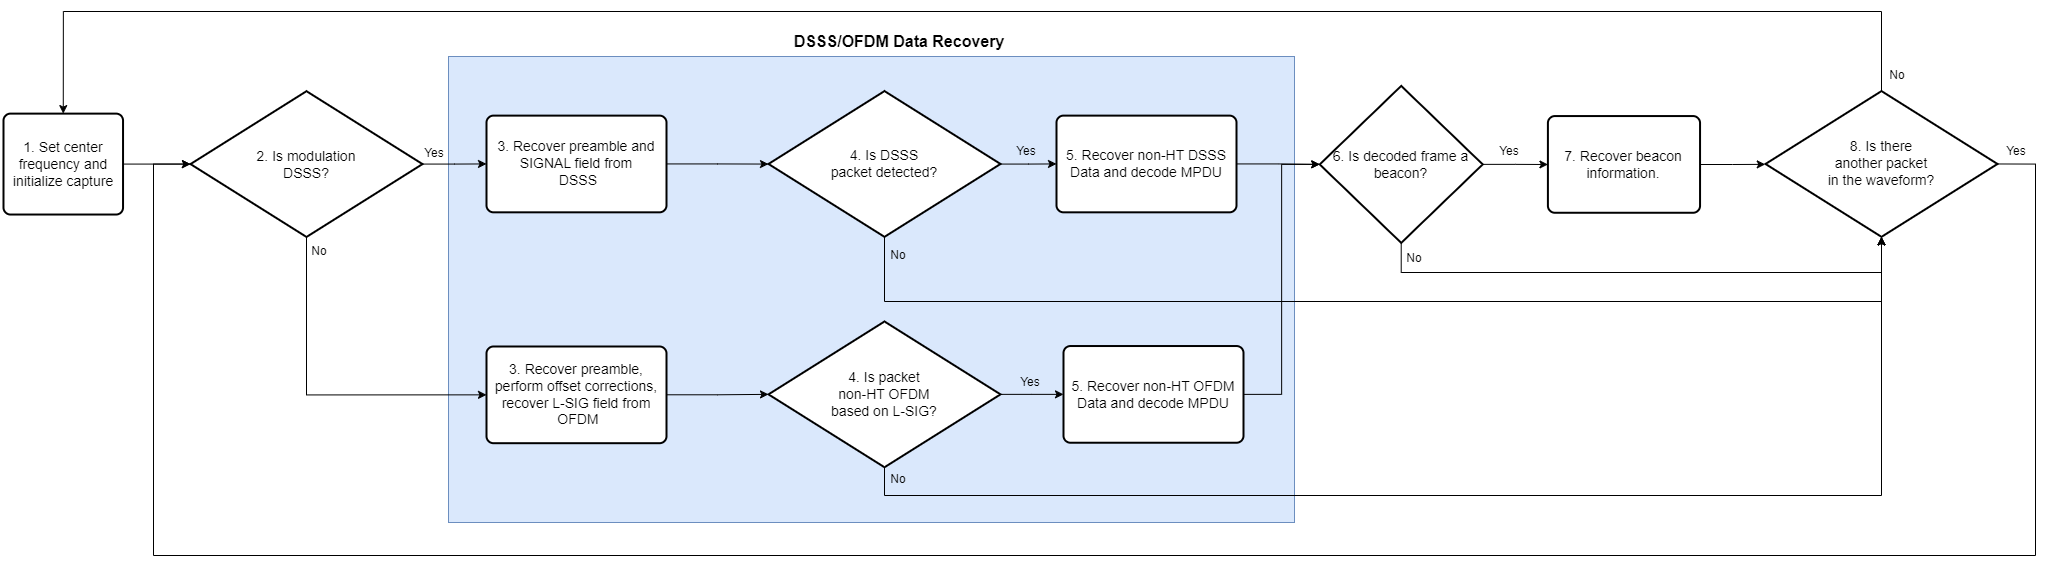

The example performs these steps to detect beacons:

- Set the center frequency of the SDR, then initialize the capture of a waveform for a set duration.

- Perform DSSS or OFDM signal recovery based on the selected configuration. 

- For OFDM, determine and apply frequency and timing corrections on the waveform, then attempt to recover the legacy signal (L-SIG) field bits. For DSSS, recover the preamble and the SIGNAL field bits.

- Check if a packet is detected. For OFDM, also check if it is a non-HT packet.

- From the recovered L-SIG/SIGNAL field, extract the modulation and coding scheme (MCS) and the length of the PLCP service data unit (PSDU). Then, recover the non-HT data and subsequently decode the MAC protocol data unit (MPDU).

- Using the recovered MAC frame configuration, check if the non-HT packet is a beacon.

- Recover the SSID, BSSID, vendor of the AP, SNR, primary operating channel, current channel center frequency index, supported channel width, frequency band, and wireless standard used by the AP.

- If the waveform contains another packet that you can decode, restart from step 2. Otherwise restart from step 1.

**Begin Packet Capture and Processing**

Create a structure for the APs that stores this information for each successfully decoded beacon.

- SSID

- BSSID

- Vendor of AP

- Signal-to-noise ratio (SNR)

- Primary operating channel

- Current channel center frequency index

- Channel width 

- Frequency band

- Operating mode supported by the AP

- MAC frame configuration

- Waveform in which the beacon exists

- Index value at which the non-HT beacon packet begins in the captured waveform

APs = struct(...
    "SSID",[],"BSSID",[],"Vendor",[],"SNR_dB",[],"Beacon_Channel",[], ...
    "Operating_Channel",[],"Channel_Width_MHz",[],"Band",[],"Mode",[], ...
    "MAC_Config",wlanMACFrameConfig,"Waveform",[],"Offset",[]);
indexAP = 1;

Scan and decode for the specified channels.

for i = 1:length(rxsim.ChannelNumbers)
    fprintf("Scanning channel %d on band %.1f.\n",rxsim.ChannelNumbers(i),rxsim.FrequencyBand);
    if rxsim.ReceiveOnSDR
        sdrReceiver.CenterFrequency = rxsim.CenterFrequencies(i);
        capturedData = capture(sdrReceiver,rxsim.CaptureTime);
    else
        capturedData = rx.capturedWaveforms(:,i);
    end

    % Display spectrum and spectrogram
    if displayScope %#ok<*UNRCH>
        scope = spectrumAnalyzer(ViewType="spectrum-and-spectrogram",SampleRate=rxsim.RadioSampleRate,...
            TimeSpanSource="property",TimeSpan=seconds(rxsim.CaptureTime));
        scope.Title = "Band: " + rxsim.FrequencyBand + " Channel: " + rxsim.ChannelNumbers(i);
        scope(capturedData);
    end

    % Resample the captured data to basesband sample rate for beacon processing
    if overSampFac ~= 1
        capturedData = resample(capturedData,bbSampleRate,rxsim.RadioSampleRate);
    end

    searchOffset = 0;
    while searchOffset < length(capturedData)

        if(strcmp(config,'DSSS, band 2.4'))
            [bitsData,decParams,searchOffset,res] = recoverDSSSBits(capturedData,searchOffset);
        else
            [bitsData,decParams,searchOffset,res] = recoverOFDMBits(capturedData,searchOffset);
        end

        if ~isempty(bitsData)
            [cfgMAC, ~, decodeStatus] = wlanMPDUDecode(bitsData, ...
                SuppressWarnings=true);

            % Print additional information on all successfully recovered packets
            if ~decodeStatus && displayAdditionalInfo
                payloadSize = floor(length(bitsData)/8);
                if(strcmp(config,'DSSS, band 2.4'))
                    fprintf("Payload Size: %d | Modulation: %s | Data Rate: %s \n",payloadSize,decParams.modulation,decParams.dataRate);
                else
                    fprintf("Payload Size: %d | Modulation: %s | Code Rate: %s \n",payloadSize,decParams.modulation,decParams.coderate);
                end
                fprintf("Type: %s | Sub-Type: %s",cfgMAC.getType,cfgMAC.getSubtype);

            end

            % Extract information about channel from the beacon.
            if ~decodeStatus && matches(cfgMAC.FrameType,"Beacon")
                % Populate the table with information about the beacon.
                if isempty(cfgMAC.ManagementConfig.SSID)
                    APs(indexAP).SSID = "Hidden";
                else
                    APs(indexAP).SSID = string(cfgMAC.ManagementConfig.SSID);
                end

                APs(indexAP).BSSID = string(cfgMAC.Address3);
                if retrieveVendorInfo
                    APs(indexAP).Vendor = determineVendor(cfgMAC.Address3);
                else
                    APs(indexAP).Vendor = "Skipped";
                end
                [APs(indexAP).Mode, APs(indexAP).Channel_Width_MHz, operatingChannel,primaryChannel] = ...
                    determineMode(cfgMAC.ManagementConfig.InformationElements);

                if isempty(operatingChannel)
                    % Default to scanning channel if operating channel
                    % cannot be determined.
                    operatingChannel = rxsim.ChannelNumbers(i);
                end

                if(rxsim.ChannelNumbers(i)~=primaryChannel)
                    % Skip the iteration if the current search channel is
                    % not the primary channel.
                    APs = APs(1:indexAP-1);
                    continue;
                end

                fprintf("%s beacon detected on channel %d in band %.1f.\n",APs(indexAP).SSID,rxsim.ChannelNumbers(i),rxsim.FrequencyBand);

                APs(indexAP).Beacon_Channel = primaryChannel;
                APs(indexAP).Operating_Channel = operatingChannel;
                if(~strcmp(config,'DSSS, band 2.4'))
                    APs(indexAP).SNR_dB = res.LLTFSNR;
                end
                APs(indexAP).MAC_Config = cfgMAC;
                APs(indexAP).Offset = res.PacketOffset;
                APs(indexAP).Waveform = capturedData;
                indexAP = indexAP + 1;
            end
        end
    end
end

Scanning channel 52 on band 5.0.


WLAN_5G beacon detected on channel 52 in band 5.0.


Scanning channel 56 on band 5.0.


w-inside beacon detected on channel 56 in band 5.0.
w-mobile beacon detected on channel 56 in band 5.0.
w-guest beacon detected on channel 56 in band 5.0.


Scanning channel 157 on band 5.0.


w-inside beacon detected on channel 157 in band 5.0.
w-mobile beacon detected on channel 157 in band 5.0.
w-guest beacon detected on channel 157 in band 5.0.


Convert the `APs` structure to a table and display the information specified in step 6 by using the local function `generateBeaconTable`.

detectedBeaconsInfo = generateBeaconTable(APs,rxsim.FrequencyBand,retrieveVendorInfo,config)

detectedBeaconsInfo = 7×9 table
       SSID           BSSID                    Vendor                 SNR (dB)      Primary Operating Channel    Current Channel Center Frequency Index    Channel Width (MHz)            Band               Mode   
    __________    ______________    ____________________________    ____________    _________________________    ______________________________________    ___________________    ____________________    __________

    "WLAN_5G"     "04D4C451C584"    "ASUSTek COMPUTER INC."         3.456965e+01      5.20000000000000e+01                5.00000000000000e+01                    "160"           5.00000000000000e+00    "802.11ax"
    "w-inside"    "B0B

if rxsim.ReceiveOnSDR
    release(sdrReceiver);
end

## Further Exploration

- The `detectedBeaconsInfo` table shows only key information about the APs. To get further information about the beacons, such as data rates supported by the AP, explore the MAC frame configuration in the `APs` structure.

- If you have access to a configurable AP, change the channel width of your AP and rerun the example to confirm the channel width.

## Local Functions

These functions assist in processing the incoming beacons.

function vendor = determineVendor(mac)
% DETERMINEVENDOR returns the vendor name of the AP by extracting the
% organizationally unique identifier (OUI) from the specified MAC address.

persistent ouis

vendor = strings(0);
try
    if isempty(ouis)
        if ~exist("oui.csv","file")
            disp("Downloading oui.csv from IEEE Registration Authority...")
            options = weboptions("Timeout",10);
            websave("oui.csv","http://standards-oui.ieee.org/oui/oui.csv",options);

        end
        ouis = readtable("oui.csv",VariableNamingRule="preserve");
    end

    % Extract OUI from MAC Address.
    oui = mac(1:6);

    % Extract vendors name based on OUI.
    vendor = string(cell2mat(ouis.("Organization Name")(matches(ouis.Assignment,oui))));

catch ME
    % Rethrow caught error as warning.
    warning(ME.message+"\nTo skip the determineVendor function call, set retrieveVendorInfo to false.",[]);
end

if isempty(vendor)
    vendor = "Unknown";
end

end

function [mode,bw,operatingChannel,primaryChannel] = determineMode(informationElements)
% DETERMINEMODE determines the 802.11 standard that the AP uses.
% The function checks for the presence of HT, VHT, and HE capability
% elements and determines the 802.11 standard that the AP uses. The element
% IDs are defined in IEEE Std 802.11-2020 and IEEE Std 802.11ax-2021.


elementIDs = cell2mat(informationElements(:,1));
IDs = elementIDs(:,1);

if any(elementIDs(IDs==255,2)==35)
    % HE Packet Format
    mode = "802.11ax";
    htElement = informationElements{IDs==61,2};
    if(any(IDs==191))
        vhtElement = informationElements{IDs==192,2};
        [bw,operatingChannel] = determineChannelWidth(htElement,vhtElement);
    else
        [bw,operatingChannel] = determineChannelWidth(htElement);
    end
elseif any(IDs==191)
    % VHT Packet Format
    mode = "802.11ac";
    vhtElement = informationElements{IDs==192,2};
    htElement = informationElements{IDs==61,2};
    [bw,operatingChannel] = determineChannelWidth(htElement,vhtElement);
elseif any(IDs==45)
    % HT Packet Format
    mode = "802.11n";
    htElement = informationElements{IDs==61,2};
    [bw,operatingChannel] = determineChannelWidth(htElement);
elseif any(IDs==3) 
    % DSSS
    mode ="802.11b";
    bw = "22";
    operatingChannel = informationElements{IDs==3,2};
else
    % Non-HT Packet Format
    mode ="802.11a/g/j/p";
    bw = "Unknown";
    operatingChannel = [];
end

if(any(IDs==45))
    primaryChannel = htElement(1);
else
    primaryChannel= informationElements{IDs==3,2};
end

end

function [bw,operatingChannel] = determineChannelWidth(htElement,varargin)
% DETERMINECHANNELWIDTH returns the bandwidth of the channel from the
% beacons operation information elements as defined in IEEE Std 802.11-2020
% Table 11-23.

msbFirst = false;

% Convert to bits to get STA channel width value in 3rd bit.
htOperationInfoBits = int2bit(htElement(2),5*8,msbFirst);
operatingChannel = 0;

if nargin == 2
    vhtElement = varargin{1};

    % VHT Operation Channel Width Field
    CW = vhtElement(1);
    % Channel Center Frequency Segment 0
    CCFS0 = vhtElement(2);
    % Channel Center Frequency Segment 1
    CCFS1 = vhtElement(3);

    if htOperationInfoBits(3) == 0
        bw = "20";
        operatingChannel = CCFS0;
    elseif CW == 0
        % HT Operation Channel Width Field is 1
        bw = "40";
        operatingChannel = CCFS0;
    elseif CCFS1 == 0
        % HT Operation Channel Width Field is 1 and
        % VHT Operation Channel Width Field is 1
        bw = "80";
        operatingChannel = CCFS0;
    elseif abs(CCFS1 - CCFS0) == 8
        % HT Operation Channel Width Field is 1 and
        % VHT Operation Channel Width Field is 1 and
        % CCFS1 is greater than 0
        bw = "160";
        operatingChannel = CCFS1;
    else
        % HT Operation Channel Width Field is 1 and
        % VHT Operation Channel Width Field is 1 and
        % CCFS1 is greater than 0 and
        % |CCFS1 - CCFS0| is greater than 16
        bw = "80+80";
    end
end

if operatingChannel == 0
    if htOperationInfoBits(3) == 1
        bw = "40";
        secondaryChannelOffset = bit2int(htOperationInfoBits(1:2),2,false);
        if secondaryChannelOffset == 1
            % Secondary Channel is above the primary channel.
            operatingChannel = htElement(1) + 2;
        elseif secondaryChannelOffset == 3
            % Secondary Channel is below the primary channel.
            operatingChannel = htElement(1) - 2;
        else
            warning("Could not determine operating channel.")
        end

    else
        bw = "20";
        operatingChannel = htElement(1);
    end
end

end

function tbl = generateBeaconTable(APs,band,retrieveVendorInfo,config)
% GENERATEBEACONTABLE converts the access point structure to a table and
% cleans up the variable names.

tbl = struct2table(APs,"AsArray",true);
tbl.Band = repmat(band,length(tbl.SSID),1);
tbl = renamevars(tbl,["SNR_dB","Beacon_Channel","Operating_Channel","Channel_Width_MHz"], ...
    ["SNR (dB)","Primary Operating Channel","Current Channel Center Frequency Index", ...
    "Channel Width (MHz)"]);

if(strcmp(config,'DSSS, band 2.4'))
    tbl = tbl(:,[1:3,5:9]);
else
    tbl = tbl(:,1:9);
end

numFields = size(tbl,2);
if retrieveVendorInfo
    tbl = tbl(:,1:numFields);
else
    tbl = tbl(:,[1:2,4:numFields]);
end


end

function [frequencyBand,bbSampleRate,chanNumber] = getSimParams(config)
% GETSIMPARAMS generates the parameters required for setting up SDRs
    switch config
        case 'DSSS, band 2.4'
            frequencyBand = 2.4;
            bbSampleRate = 11e6;
            chanNumber = 1:14;
        case 'OFDM, band 2.4'
            frequencyBand = 2.4;
            bbSampleRate = 20e6;   
            chanNumber = 1:13;
        case 'OFDM, band 5'
            frequencyBand = 5;
            bbSampleRate = 20e6;
            chanNumber = [32, 36, 40, 44, 48, 52, 56, 60, 64, 100, 104, 108, 112, 116, 120, 124, 128, 132, 136, 140, 144, 149, 153, 157, 161, 165, 169, 173, 177];
    end
end

*Copyright 2022-2024 The MathWorks, Inc.*